clear all
close all
clc


% load the data as a csv
data = readtable('Tonhoku_2011_BHZ.csv');

% python data extractor names columns
% "seconds from origin" and "velocity ms"
% use these as the x and y axis of the data
t = data.seconds_from_origin;
x = data.velocity_m_s;

% calculate the length of the data and sampling frequency
N = length(x);
dt = mean(diff(t));       % time between samples
fs = round(1 / dt);       % sampling frequency
T = t(end) - t(1);        % length

fprintf('Input Data Parameters\n');

Input Data Parameters


fprintf('Sampling frequency:   %d Hz\n', fs);

Sampling frequency:   20 Hz


fprintf('Nyquist frequency:    %.1f Hz\n', fs/2);

Nyquist frequency:    10.0 Hz


fprintf('Signal duration:      %.2f s\n',  T);

Signal duration:      59999.95 s


fprintf('Total samples:        %d\n',    N);

Total samples:        1200000


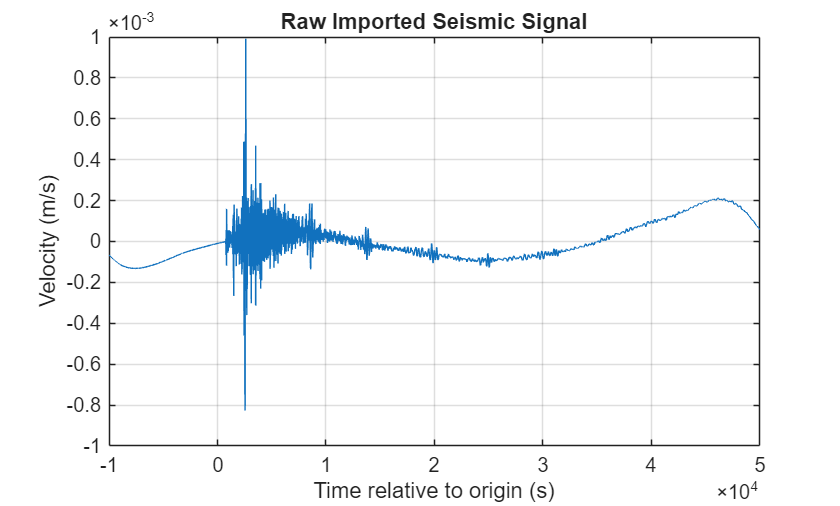


% plot the input signal
figure;
plot(t, x);
title('Raw Imported Seismic Signal');
xlabel('Time relative to origin (s)'); 
ylabel('Velocity (m/s)');
grid on;

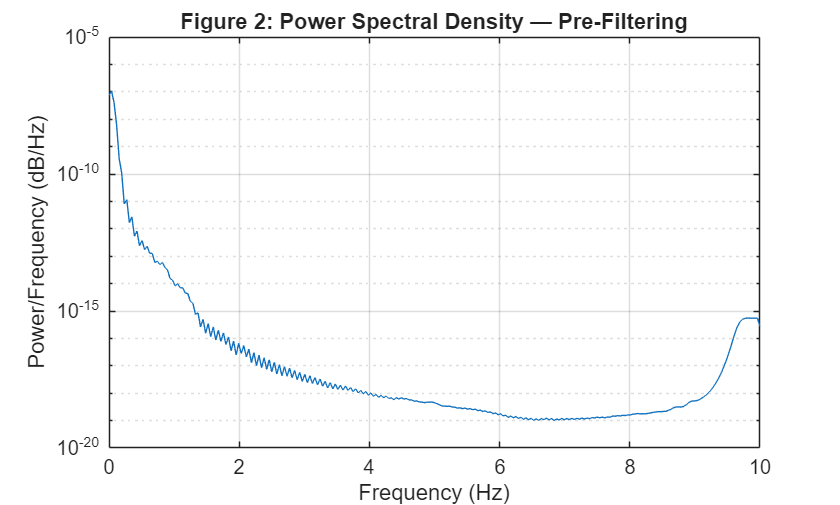

% calculate the power spectral density of the input signal to display
% frequencies of interst & what should be filtered

% calculate the PSD and plot the power on a log scale
[pxx, f] = pwelch(x, hann(256), 128, 512, fs);
semilogy(f, pxx)
title('Figure 2: Power Spectral Density — Pre-Filtering');
xlabel('Frequency (Hz)'); ylabel('Power/Frequency (dB/Hz)');
grid on;
xlim([0 fs/2]); % set the x axis to respect the nyquist frequency

% implement the FIR filter to isolate the frequencies of interest

filter_order = 64;
filter_cutoff = 0.3; %hz

filter_cutoff = 0.3000


%highpass filter with 0.3Hz cutoff to remove DC offset
hpf    = fir1(filter_order, filter_cutoff/(fs/2), 'high');

% apply the filter to the x data
x_filtered = filter(hpf, 1, x);

% recalculate the PSD
[pxx_filtered, f_filtered] = pwelch(x_filtered, hann(256), 128, 512, fs);

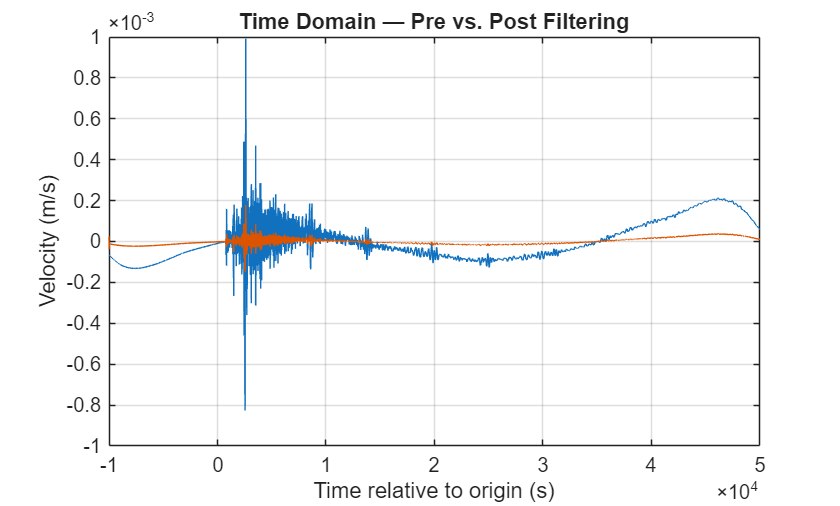

% compare the time domain and PSD plots post filter

% plot the raw signal vs the filtered one to compare
figure;
plot(t, x);
hold on;
plot(t, x_filtered);
title('Time Domain — Pre vs. Post Filtering');
xlabel('Time relative to origin (s)'); 
ylabel('Velocity (m/s)');
grid on;

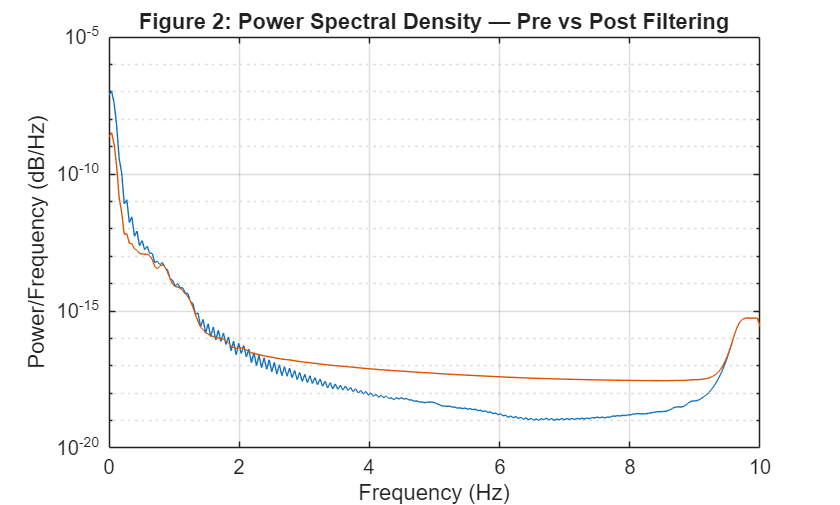


% plot the raw signal vs filtered PSD
figure;
semilogy(f, pxx)
hold on;
semilogy(f_filtered, pxx_filtered)
title('Figure 2: Power Spectral Density — Pre vs Post Filtering');
xlabel('Frequency (Hz)'); ylabel('Power/Frequency (dB/Hz)');
grid on;